t_X_SVPID = out.tout;
input_X_SVPID = out.simout.Data;
error_X_SVPID = out.simout1.Data;
CE_X_SVPID = out.simout2.Data;
offset = -0.5;
output_X_SVPID = out.simout3.Data-offset;

%save("MotorX_SVGPID.mat")

SVGX = 1.72;
CE_X_SVPIDC=ones(133,1);
if  CE_X_SVPID < 255
    CE_X_SVPIDC = (11.4/255)*SVGX*CE_X_SVPID;
else    
    CE_X_SVPIDC=CE_X_SVPIDC*11.4;
end

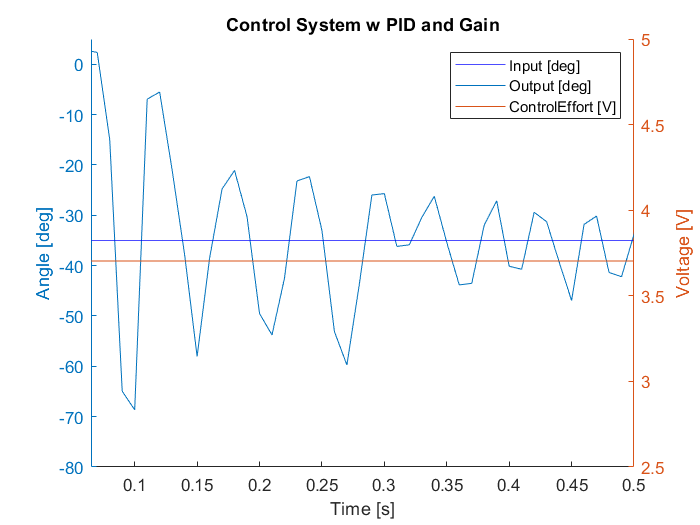

clf;
hold on
yyaxis left
yline(-35,'b')
plot(t_X_SVPID,output_X_SVPID)
ylabel('Angle [deg]')
xlabel('Time [s]')
ylim([-80 5])
xlim([0.065 0.5])

yyaxis right
plot(t_X_SVPID,CE_X_SVPIDC)
ylabel('Voltage [V]')
title('Control System w PID and Gain')
legend('Input [deg]','Output [deg]','ControlEffort [V]')

hold off